clear all
close all
clc
load ide_modelli_scara.mat

Gs1 = modello_continuo_q1;
tf(Gs1);
wn = 665;
xci_z=0.15; %aggiustate xci_z e xci_p per rendere il filtro più o meno selettivo
xci_p=0.7;
s=tf('s');
notch=(s^2+2*xci_z*wn*s+wn^2)/(s^2+2*xci_p*wn*s+wn^2);
F = 1/(0.003*s+1)

F =
 
       1
  -----------
  0.003 s + 1
 
Continuous-time transfer function.
Model Properties


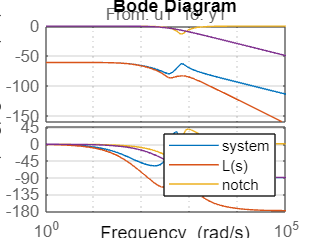

P=Gs1*notch*F;

bode(Gs1)
hold on
bode(P)
bode(notch)
bode(F)
hold off

grid on
legend('system','L(s)','notch')

wc = 150;
Kp=1/abs(freqresp(P,wc));

C=Kp

C = 3.4206e+03

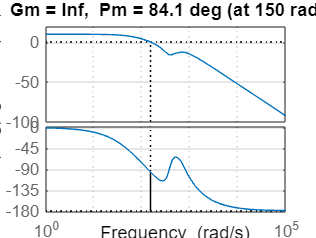

figure
margin(C*P)
grid on


loop1 = feedback(C*P,1)

loop1 =
 
  A = 
               x1          x2          x3          x4          x5          x6
   x1      -100.5       297.8      -93.35      -22.57           0       20.57
   x2       -1480      -100.5       607.1       107.4           0      -97.88
   x3   1.178e-06  -3.601e-07      -68.54      -369.6           0       336.8
   x4           0           0           0        -931      -863.7       666.7
   x5           0           0           0         512           0           0
   x6       766.4       302.5      -618.4           0           0      -333.3
 
  B = 
       u1
   x1   0
   x2   0
   x3   0
   x4   0
   x5   0
   x6  16
 
  C = 
           x1      x2      x3      x4      x5      x6
   y1   -47.9  -18.91   38.65       0       0       0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


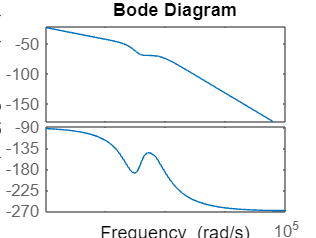

G1 = loop1*1/s;
bode(G1)

% tf(G1)


% wc_des=200;
% J=@(x)pivel_cost_function(x,G1,wc_des);
% MS=1.4;
% wh=2000;
% Fh_max=0.1;
% wl=0.1;
% Dh_max=0.1;%disturbo sul carico ridotto di almeno 10 volte
% 
% w_vector=logspace(-3,3)'; % [10^-3,10^3]
% w_vector=sort([w_vector;wl;wh]);

%nlcon=@(x)pivel_constraints(x,G1,w_vector,MS,wh,Fh_max,wl,Dh_max);%anonious function

Risolvo il problema con fmincon, la soluzione è locale.

Impongo che $K_p\in[0.01,10000]$ e $K_i\in[0.01,10000]$

%x0=[1,0.1];% scegliere un punto di partenza meglio provarne di diversi
%x=fmincon(J,x0,[],[],[],[],[0.001 0.000001],[10000 10000],nlcon)
%Kp=x(1);
%Ki=x(2);
%C1=tf([Kp Ki],[1 0])
%margin(C1*G1)
%step(feedback(C1*G1,1))